# **Assignment:  Feature Extraction of CWRU Dataset**

**Name: Jeong Woo Park**

**Given:  ****CWRU bearing dataset **

[https://engineering.case.edu/bearingdatacenter/download-data-file](https://engineering.case.edu/bearingdatacenter/download-data-file)

Classes:

-  Normal / Outer Race fault / Inner Race fault / Ball fault

**Instruction**

This Assignment is implementation a part of Feature Extration in  the literature 

- Rauber, T. W., de Assis Boldt, Fㅌ., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**1. Extract and Analyze  Features**

**2. Compare  Features among different classes**

## Dataset

Sampling: 

- **Drive end bearing(12K): 12,000 samples/second**

Classes:

- Normal / Outer Race fault / Inner Race fault

- Each under 1HP load,  fault diameter of 0.007inches

Variables

- DE - drive end accelerometer data

- FE - fan end accelerometer data

- BA - base accelerometer data

- time - time series data

- RPM - shaft rpm during testing

### Drive End Bearing Experiment- 12K

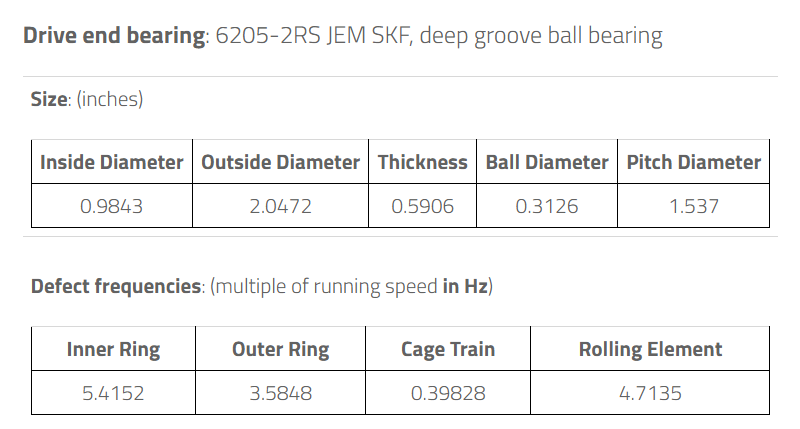

close all
clear

load('ball_007_1hp.mat')  %X119
load('inner_007_1hp.mat') %x106
load('normal_1hp.mat')    %x098
load('outer_007_1hp.mat') %x131

fs = 12000;

BPFI = 5.4152 * (X119RPM/60);
BPFO = 3.5848 * (X131RPM/60);
BSF  = 4.7135 * (X119RPM/60);

## **Analyze Features **

• Extract Time-Domain Features

• Extract Frequency-Domain Features

• Envelop Extraction

• Plot  STFT 

• Plot  Kurtogram

• Analyze Spectral Kurtosis

## 1. DE Ball Fault

First, I will analyze DE Ball Fault data.

###     1-1) DE ball time Features

        It can compare to normal time features, I wrote below compare feature part.

ball_time_DE  = timeFeatures(X119_DE_time)

ball_time_DE = 1×14 table
      mean         std        rms        sra         aav      energy     peak       ppv        if        sf        cf        mf         sk          kt  
    _________    _______    _______    ________    _______    ______    _______    ______    ______    ______    ______    ______    _________    ______

    0.0038918    0.13901    0.13907    0.094363    0.11122    2348.1    0.65965    1.2993    5.9312    1.2504    4.7433    6.9905    0.0074533    2.9638


###     1-2) DE ball Frequency Features

        It can compare to normal ball frequency features, I wrote below compare feature part.

N_ball = length(X119_DE_time);

X119_DE_freq = getFFT(X119_DE_time,N_ball);

ball_freq_DE  = freqFeatures(X119_DE_freq)

ball_freq_DE = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    0.00026423    0.00079854    0.00075356


###     1-3) DE ball Time Domain Signal

        It is a graph showing DE ball data in the time domain. There is nothing that can be detected by noise.

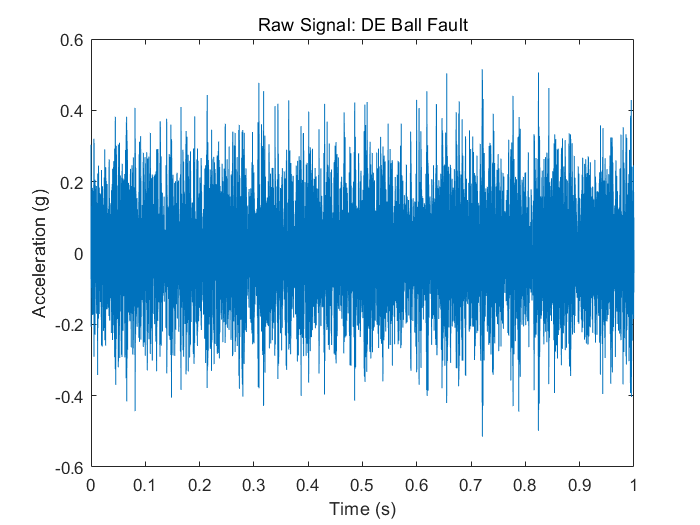

figure
tball_DE = (0:length(X119_DE_time)-1)/fs;
plot(tball_DE, X119_DE_time)
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Raw Signal: DE Ball Fault')
xlim([0 1])

###     1-4) DE ball **Kurtosis**

        Check kurtosis of DE ball data in the time domain.

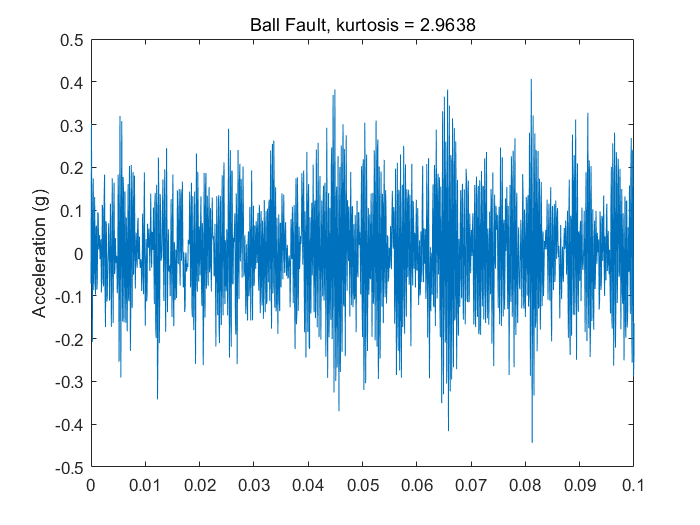

kurtball = kurtosis(X119_DE_time);

% Plot
figure
plot(tball_DE, X119_DE_time)
ylabel('Acceleration (g)')
title(['Ball Fault, kurtosis = ' num2str(kurtball)])
xlim([0 0.1])

###     1-5) DE ball FFT

        FFT was performed to see the frequency of the DE ball raw data.

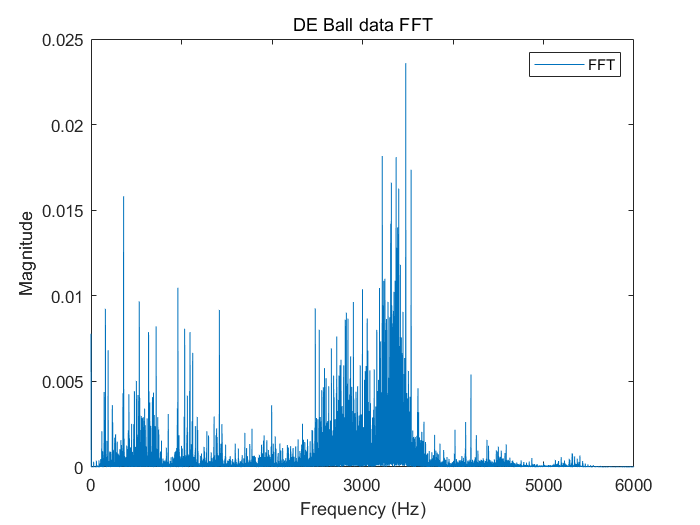

figure
f_ball = 0:fs/N_ball:fs/2;
plot(f_ball, X119_DE_freq)
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('DE Ball data FFT')
legend('FFT')

###     1-6) DE ball PSD

        PSD was used to see the square of the DE ball FFT signal.

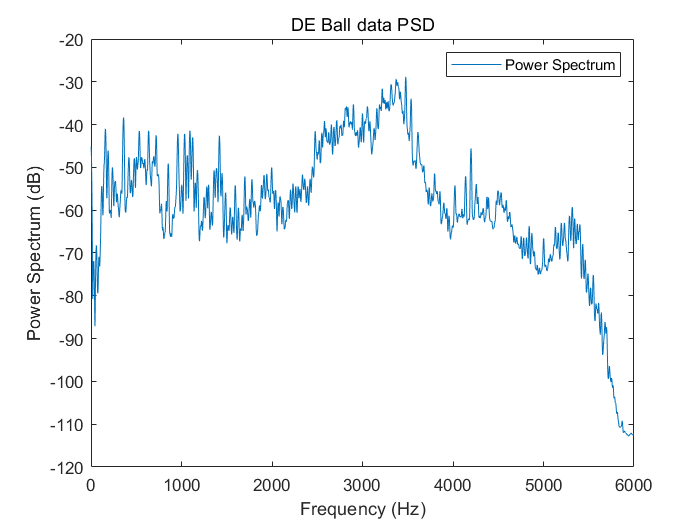

[pball, fpball] = pspectrum(X119_DE_time,fs);

% Plot
figure
plot(fpball, 10*log10(pball))
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('DE Ball data PSD')
legend('Power Spectrum')

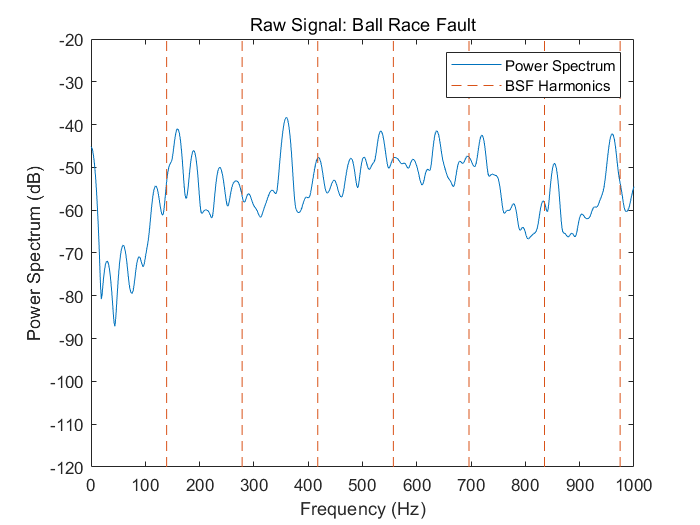

figure
plot(fpball, 10*log10(pball))
ncomb = 10;
helperPlotCombs(ncomb, BSF)
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Ball Race Fault')
legend('Power Spectrum', 'BSF Harmonics')
xlim([0 1000])

###      1-7) DE ball STFT

          STFT is used to see the frequency distribution over time in ball fault data.

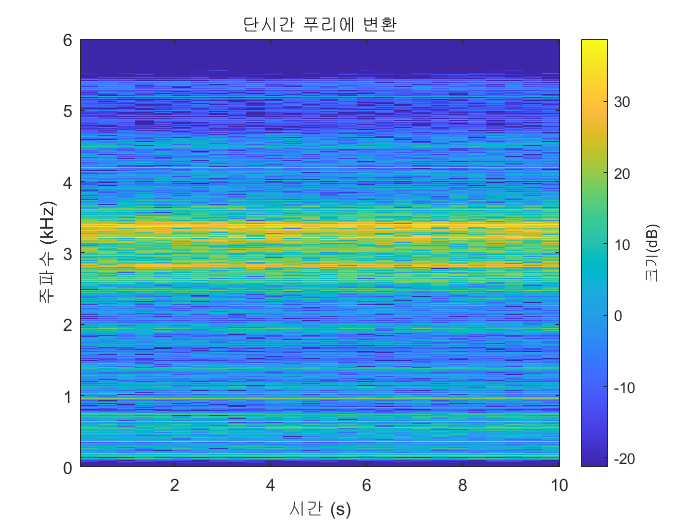

figure
stft(X119_DE_time,fs,'Window',hamming(5120,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');

###      1-8) DE ball Envelope signal

        There is a lot of noise in raw data in front. The envelope method was used to eliminate noise.

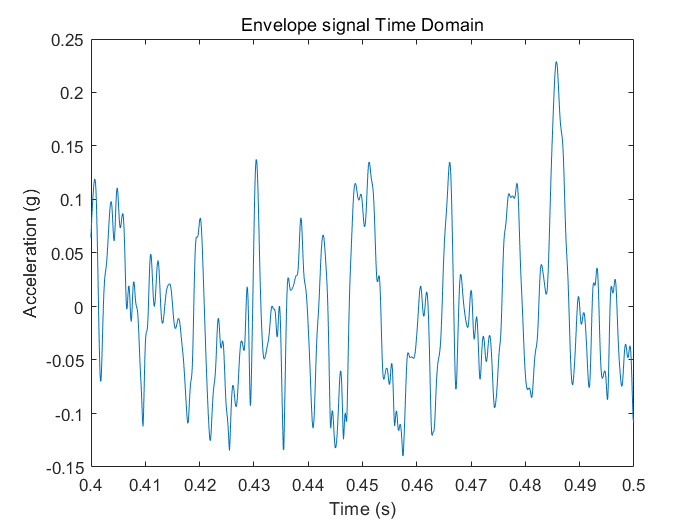

[pEnvball, fEnvball, xEnvball, tEnvball] = envspectrum(X119_DE_time,fs);

% Plot
figure
plot(tEnvball, xEnvball)
xlim([0.4 0.5])
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal Time Domain')

###     1-9) Ball Envelope FFT

        FFT was used to see the square of the DE ball envelope signal.

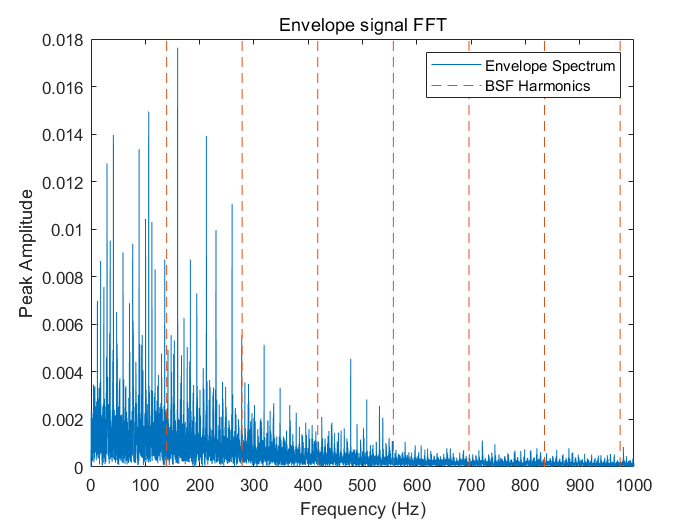

figure
plot(fEnvball, pEnvball)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, BSF)
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: Ball Race Fault')
legend('Envelope Spectrum', 'BSF Harmonics'),title('Envelope signal FFT')

###     1-10) DE ball kurtogram

         Frequency, Band Width, and Window size may be obtained through Kourtogram..

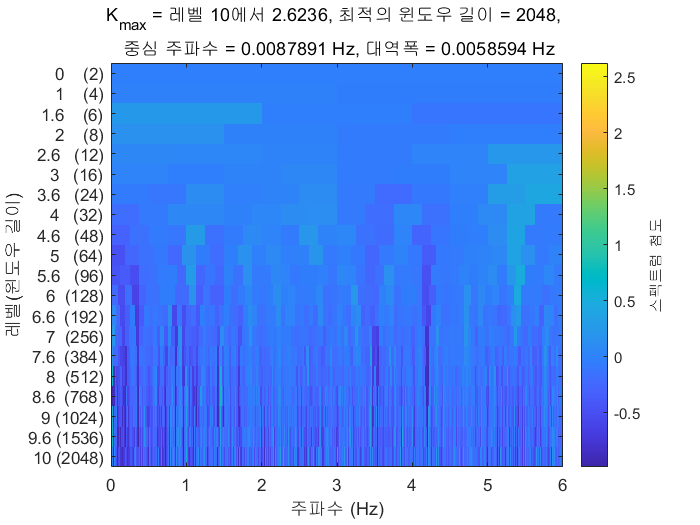

figure
kurtogram(X119_DE_time,12);

[~, ~, ~, fc_ball, wc_ball, BW_ball] =kurtogram(X119_DE_time, fs, 6)

fc_ball = 5.4375e+03

wc_ball = 96

BW_ball = 125

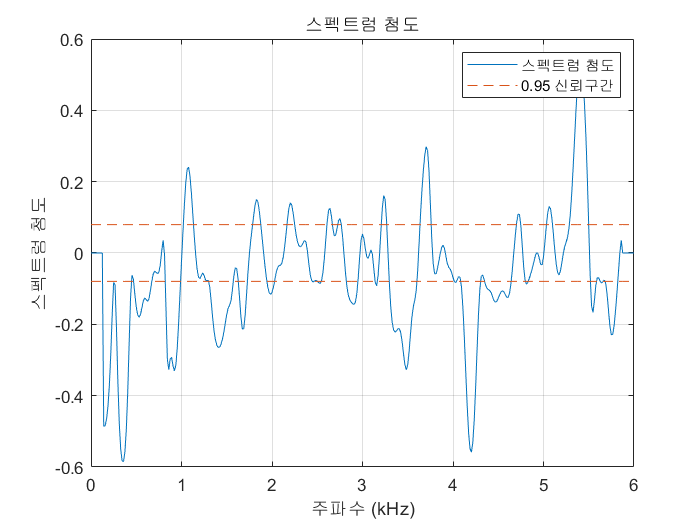

pkurtosis(X119_DE_time,fs,wc_ball)

###     1-11) DE ball band pass filter

        Design a bandpass filter with the values obtained through Kurtogram.

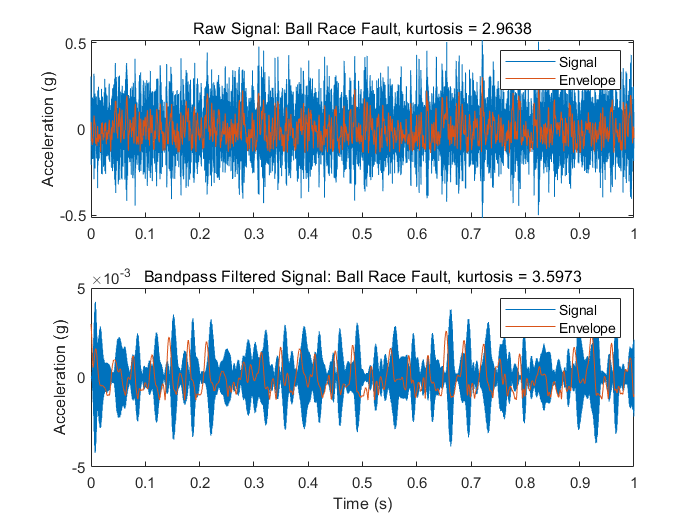

% Design bandpass filter
bpf_Ball = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', fc_ball-BW_ball/2, ...
    'CutoffFrequency2', fc_ball+BW_ball/2, 'SampleRate', fs); 

% Apply bandpass filter
xBallBpf = filter(bpf_Ball, X119_DE_time);

% Calculate Kurtosis
kurtBallBpf = kurtosis(xBallBpf);


% Apply bandpass filtered envelope spectrum
[pEnvBallBpf, fEnvBallBpf, xEnvBallBpf, tEnvBpfBall] = envspectrum(X119_DE_time, fs, ...
    'FilterOrder', 200, 'Band', [fc_ball-BW_ball/2 fc_ball+BW_ball/2]);

figure
subplot(2, 1, 1)
plot(tball_DE, X119_DE_time,tEnvball, xEnvball)
ylabel('Acceleration (g)')
title(['Raw Signal: Ball Race Fault, kurtosis = ', num2str(kurtball)])
xlim([0 1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(tball_DE, xBallBpf, tEnvBpfBall, xEnvBallBpf)
ylabel('Acceleration (g)')
xlim([0 1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Ball Race Fault, kurtosis = ', num2str(kurtBallBpf)])
legend('Signal', 'Envelope')

###     1-12) DE ball Bandpass Filter Envelope plot

        Look at the envelope signal to which the band pass filter is applied.

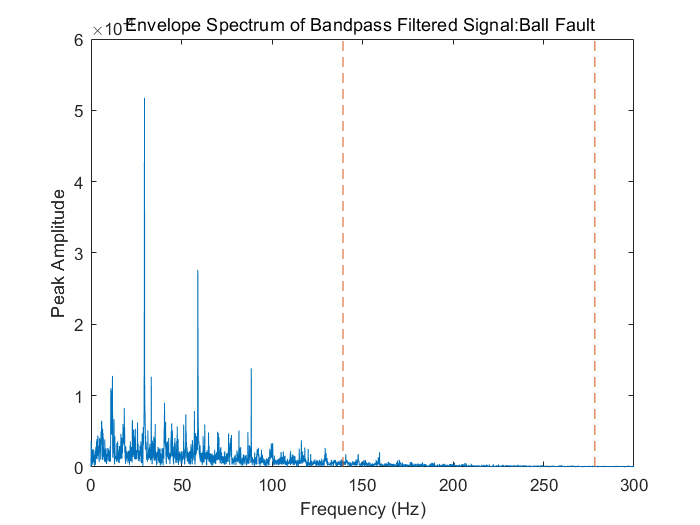

figure
plot(fEnvBallBpf, pEnvBallBpf);
ncomb = 10;
helperPlotCombs(ncomb, BSF);
xlim([0 300])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum of Bandpass Filtered Signal:Ball Fault ')

## 2. DE Inner Fault

Second, I will analyze DE Inner Fault data.

###     2-1) DE Inner time Features

        It can compare to normal time features, I wrote below compare feature part.

inner_time_DE  = timeFeatures(X106_DE_time)

inner_time_DE = 1×14 table
      mean        std        rms        sra        aav      energy     peak      ppv        if        sf        cf        mf        sk         kt  
    ________    _______    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    _______    ______

    0.005801    0.29284    0.29289    0.16484    0.20764    10465     1.5808    2.9838    7.6131    1.4105    5.3973    9.5902    0.13043    5.5423


###     2-2) DE Inner Frequency Features

        It can compare to normal ball frequency features, I wrote below compare feature part.

N_inner = length(X106_DE_time)-1;

X106_DE_freq = getFFT(X106_DE_time,N_inner);
inner_freq_DE  = freqFeatures(X106_DE_freq)

inner_freq_DE = 1×3 table
        fc          rmsf          rvf   
    __________    _________    _________

    0.00051102    0.0016775    0.0015978


###     2-3) DE Inner Time Domain Signal

        It is a graph showing DE Inner data in the time domain. There is nothing that can be detected by noise.

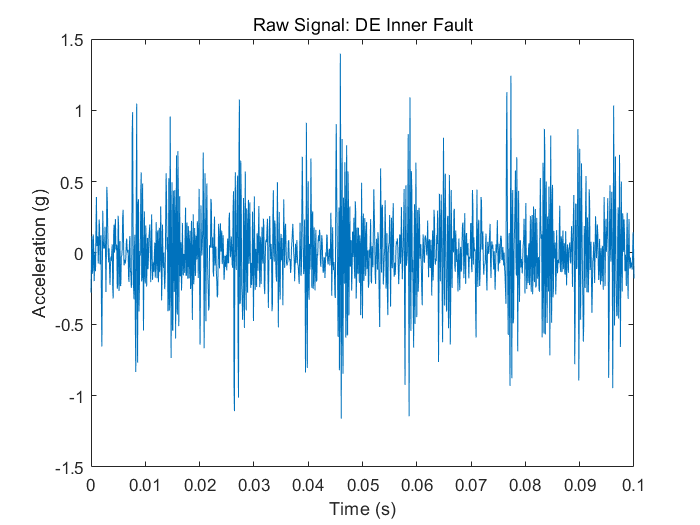

figure
tinner_DE = (0:length(X106_DE_time)-1)/fs;
plot(tinner_DE, X106_DE_time)
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Raw Signal: DE Inner Fault')
xlim([0 0.1])

###      2-4) DE Inner **Kurtosis**

         Check kurtosis of DE Inner data in the time domain.

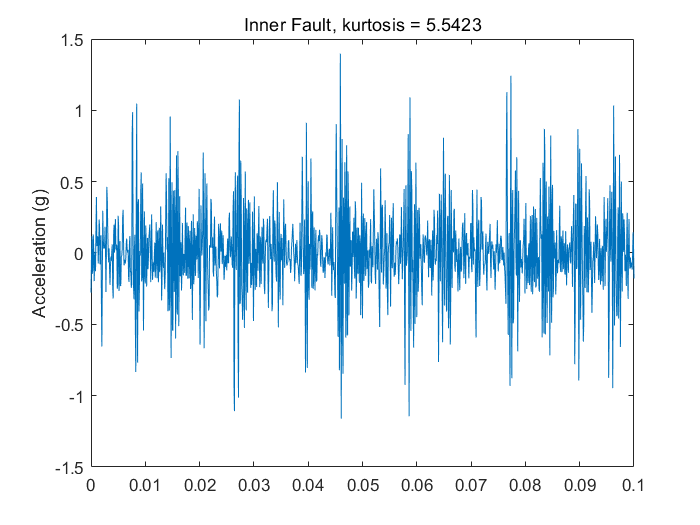

kurtinner = kurtosis(X106_DE_time);

% Plot
figure
plot(tinner_DE, X106_DE_time)
ylabel('Acceleration (g)')
title(['Inner Fault, kurtosis = ' num2str(kurtinner)])
xlim([0 0.1])

###     2-5) DE Inner FFT

         FFT was performed to see the frequency of the DE Inner raw data.

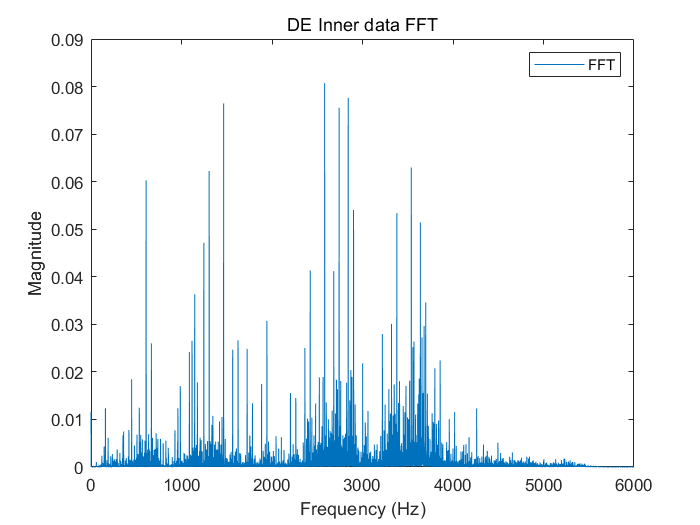

figure
f_inner = 0:fs/N_inner:fs/2;
plot(f_inner, X106_DE_freq)
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('DE Inner data FFT')
legend('FFT')

###     2-6) DE Inner PSD

        PSD was used to see the square of the DE Inner FFT signal.

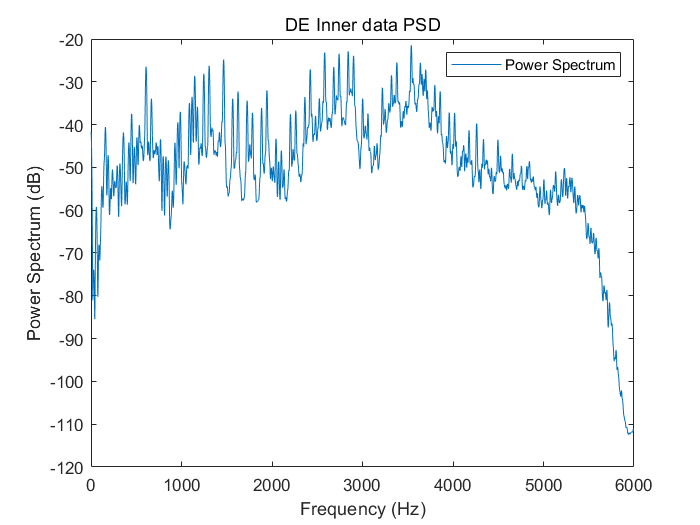

[pinner, fpinner] = pspectrum(X106_DE_time,fs);

% Plot
figure
plot(fpinner, 10*log10(pinner))
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('DE Inner data PSD')
legend('Power Spectrum')

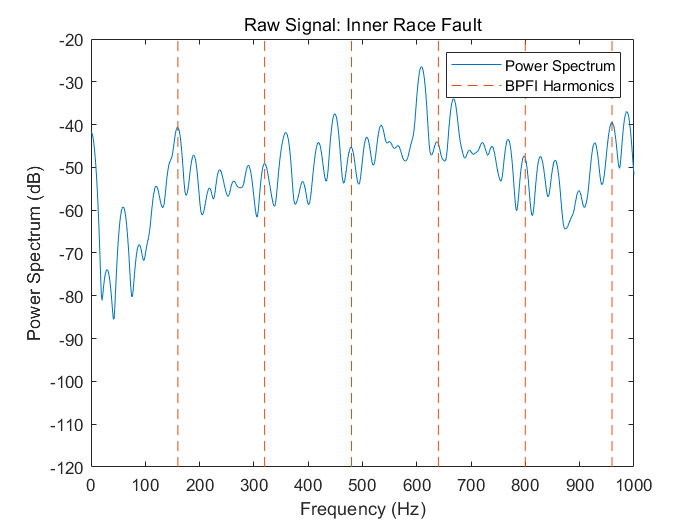

figure
plot(fpinner, 10*log10(pinner))
ncomb = 10;
helperPlotCombs(ncomb, BPFI)
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Inner Race Fault')
legend('Power Spectrum', 'BPFI Harmonics')
xlim([0 1000])

###      2-7) DE Inner STFT

          STFT is used to see the frequency distribution over time in inner fault data.

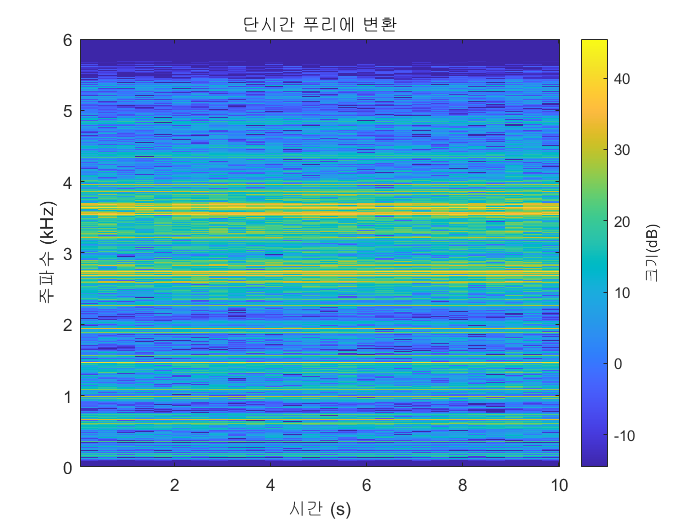

figure
stft(X106_DE_time,fs,'Window',hamming(5120,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');

###      2-8) Inner Envelope Extraction

         There is a lot of noise in raw data in front. The envelope method was used to eliminate noise.

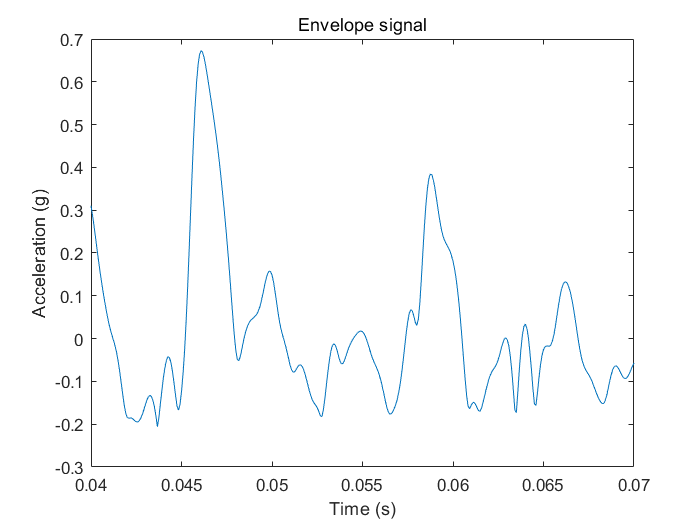

[pEnvInner, fEnvInner, xEnvInner, tEnvInner] = envspectrum(X106_DE_time,fs);


% Plot
figure
plot(tEnvInner, xEnvInner)
xlim([0.04 0.07])
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal')

###      2-9) Inner Envelope FFT

         FFT was used to see the square of the DE inner envelope signal.

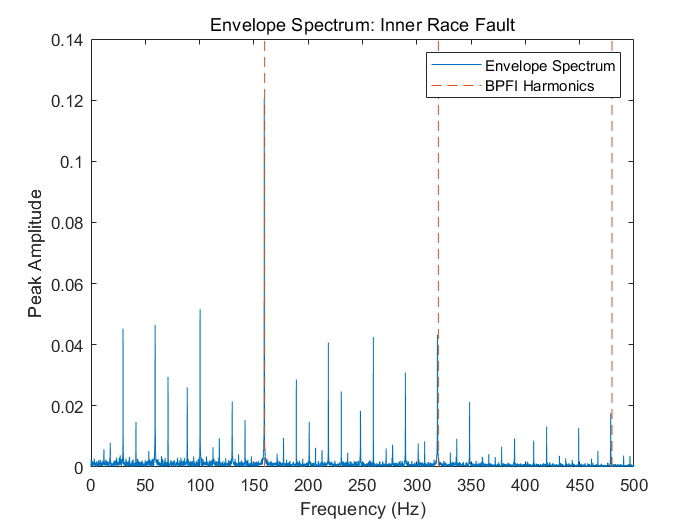

figure
plot(fEnvInner, pEnvInner)
xlim([0 500])
ncomb = 10;
helperPlotCombs(ncomb, BPFI)
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: Inner Race Fault')
legend('Envelope Spectrum', 'BPFI Harmonics')

###       2-10) DE Inner kurtogram

          Frequency, Band Width, and Window size may be obtained through Kourtogram..

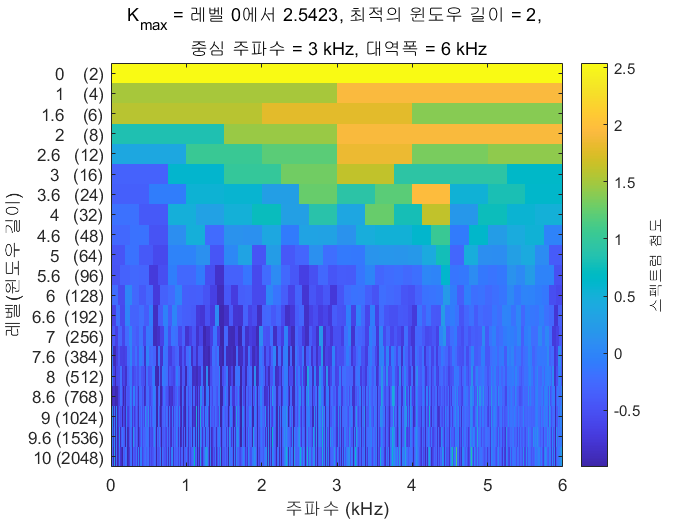

figure
kurtogram(X106_DE_time,fs);

[~, ~, ~, fc_inner, wc_inner, BW_inner] =kurtogram(X106_DE_time, fs,3)

fc_inner = 3000

wc_inner = 2

BW_inner = 6000

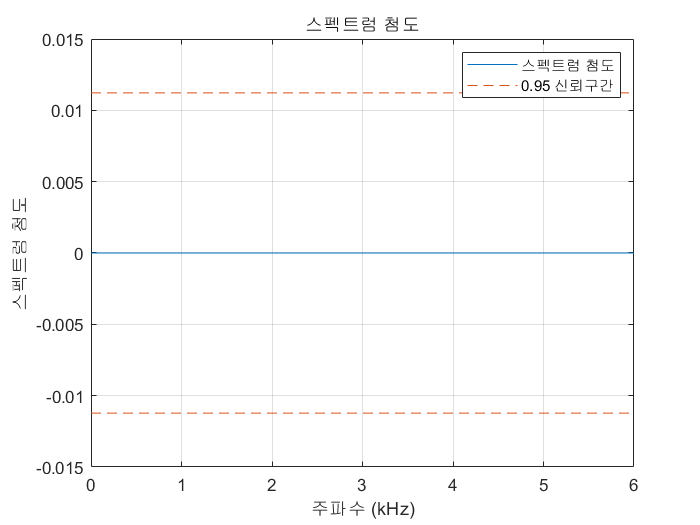

pkurtosis(X106_DE_time,fs,wc_inner);

###      2-11) DE Inner band pass filter

        Design a bandpass filter with the values obtained through Kurtogram.

% Design bandpass filter
bpf_Inner = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', 3000, ...
    'CutoffFrequency2', 4000, 'SampleRate', fs);

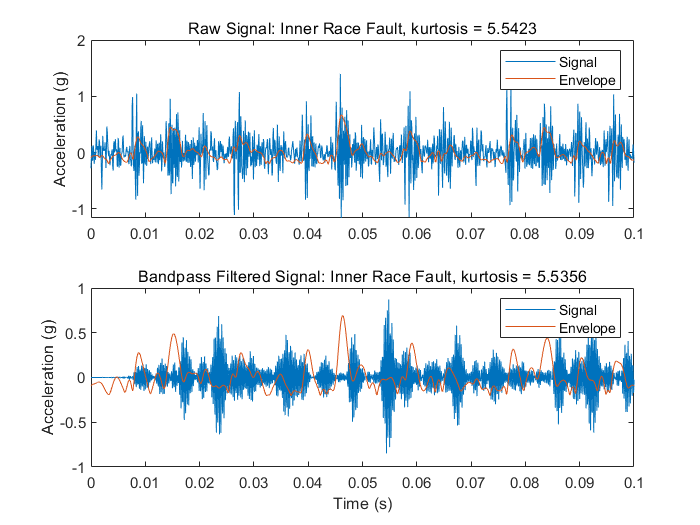

% Apply bandpass filter
xInnerBpf = filter(bpf_Inner, X106_DE_time);

% Calculate Kurtosis
kurtInnerBpf = kurtosis(xInnerBpf);

% Apply bandpass filtered envelope spectrum
[pEnvInnerBpf, fEnvInnerBpf, xEnvInnerBpf, tEnvBpfInner] = envspectrum(X106_DE_time, fs, ...
    'FilterOrder', 200, 'Band',[3000 4000]);

figure
subplot(2, 1, 1)
plot(tinner_DE, X106_DE_time,tEnvInner, xEnvInner)
ylabel('Acceleration (g)')
title(['Raw Signal: Inner Race Fault, kurtosis = ', num2str(kurtinner)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(tinner_DE, xInnerBpf, tEnvBpfInner, xEnvInnerBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Inner Race Fault, kurtosis = ', num2str(kurtInnerBpf)])
legend('Signal', 'Envelope')

###      2-12) DE Ball Bandpass Filter Envelope plot

        Look at the envelope signal to which the band pass filter is applied.

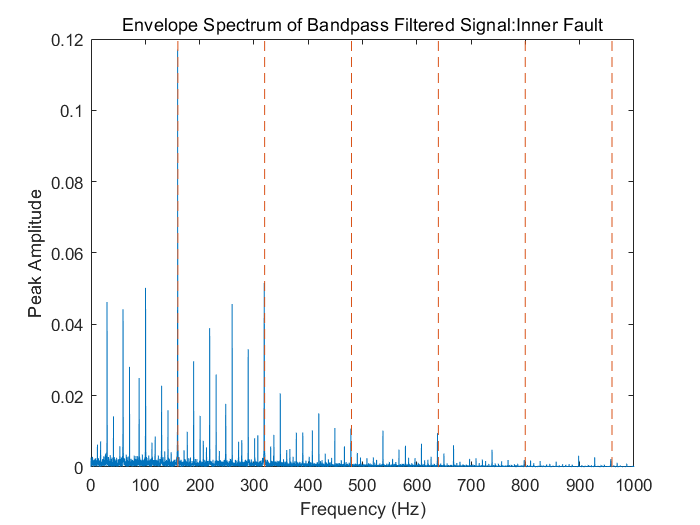

figure
plot(fEnvInnerBpf, pEnvInnerBpf);
ncomb = 10;
helperPlotCombs(ncomb, BPFI)
xlim([0 1000])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum of Bandpass Filtered Signal:Inner Fault')

## 3. DE Outer Fault

Third, I will analyze DE Outer Fault data.

###     3-1) DE Outer time Features

        It can compare to normal time features, I wrote below compare feature part.

outer_time_DE  = timeFeatures(X131_DE_time)

outer_time_DE = 1×14 table
      mean         std        rms        sra        aav      energy     peak      ppv        if        sf        cf        mf         sk        kt  
    _________    _______    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    ________    _____

    0.0040611    0.59194    0.59195    0.26626    0.36646    42898     3.1123    6.1242    8.4927    1.6153    5.2577    11.689    0.033401    7.595


###     3-2) DE Outer Frequency Features

        It can compare to normal Outer frequency features, I wrote below compare feature part.

N_outer = length(X131_DE_time);

X131_DE_freq = getFFT(X131_DE_time,N_outer);

outer_freq_DE  = freqFeatures(X131_DE_freq)

outer_freq_DE = 1×3 table
        fc          rmsf          rvf   
    __________    _________    _________

    0.00083666    0.0033836    0.0032786


###     3-3) DE Outer Time Domain Signal

        It is a graph showing DE Outer data in the time domain. There is nothing that can be detected by noise.

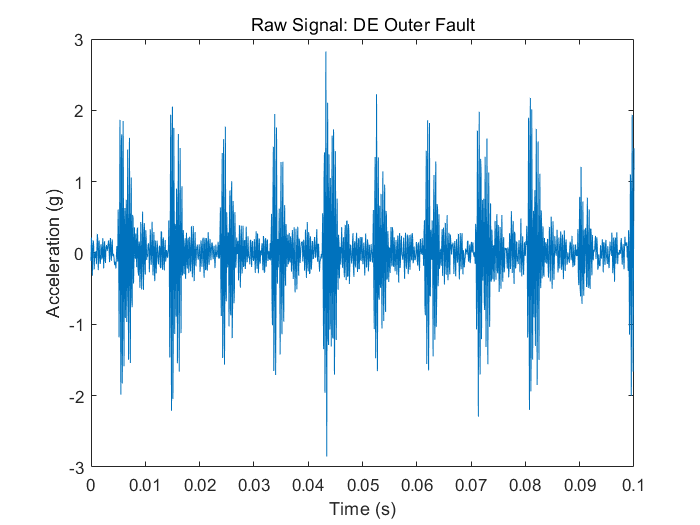

figure
touter_DE = (0:length(X131_DE_time)-1)/fs;
plot(touter_DE, X131_DE_time)
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Raw Signal: DE Outer Fault')
xlim([0 0.1])

###     3-4) DE Outer **Kurtosis**

         Check kurtosis of DE Outer data in the time domain.

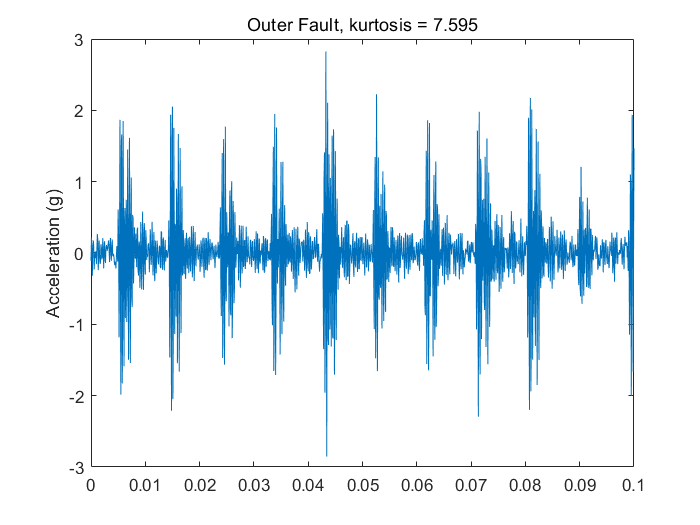

kurtouter = kurtosis(X131_DE_time);

% Plot
figure
plot(touter_DE, X131_DE_time)
ylabel('Acceleration (g)')
title(['Outer Fault, kurtosis = ' num2str(kurtouter)])
xlim([0 0.1])

###     3-5) DE Outer FFT

         FFT was performed to see the frequency of the DE Inner raw data.

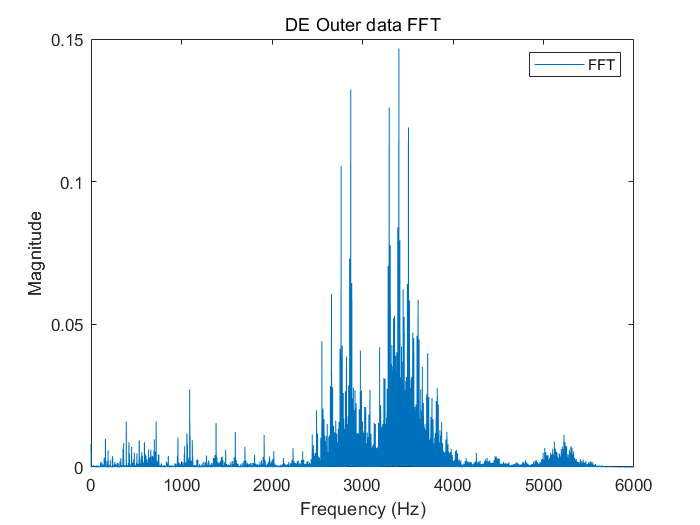

figure
f_outer = 0:fs/N_outer:fs/2;
plot(f_outer, X131_DE_freq)
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('DE Outer data FFT')
legend('FFT')

###     3-6) DE outer PSD

        PSD was used to see the square of the DE Outer FFT signal.

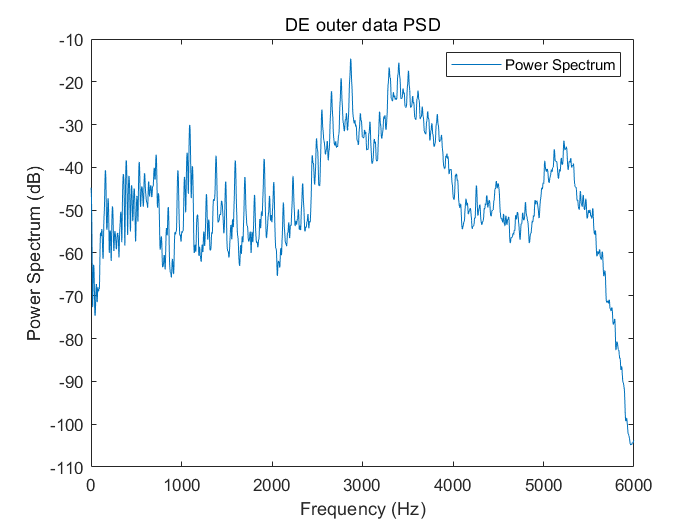

[pouter, fpouter] = pspectrum(X131_DE_time,fs);

% Plot
figure
plot(fpouter, 10*log10(pouter))
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('DE outer data PSD')
legend('Power Spectrum')

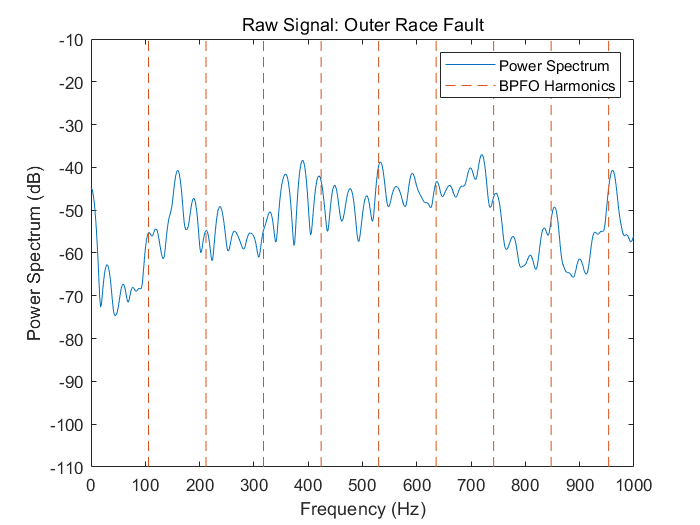

figure
plot(fpouter, 10*log10(pouter))
ncomb = 10;
helperPlotCombs(ncomb, BPFO)
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Outer Race Fault')
legend('Power Spectrum', 'BPFO Harmonics')
xlim([0 1000])

###    3-7) DE Outer STFT

          STFT is used to see the frequency distribution over time in Outer fault data.

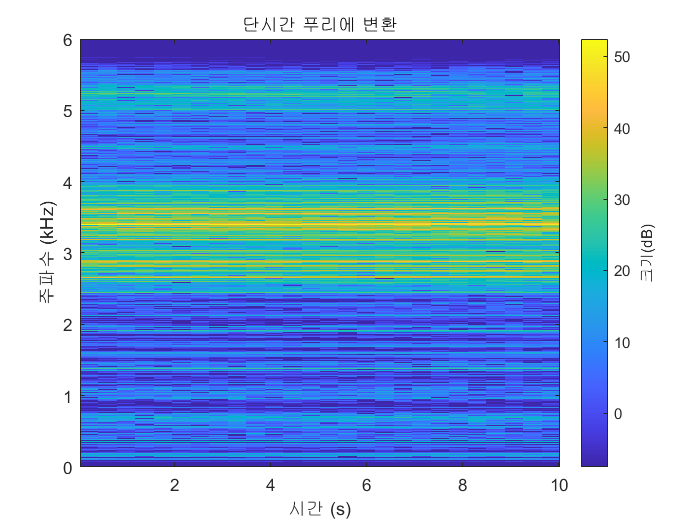

figure
stft(X131_DE_time,fs,'Window',hamming(5120,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');

###     3-8) DE outer Envelope signal

         There is a lot of noise in raw data in front. The envelope method was used to eliminate noise.

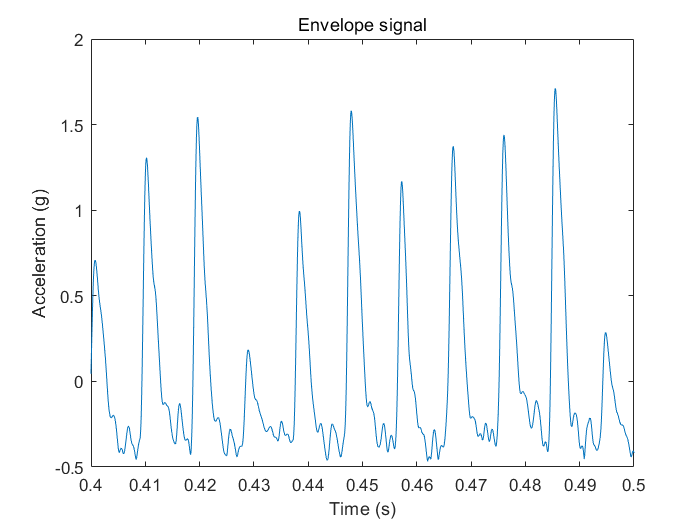

[pEnvOuter, fEnvOuter, xEnvOuter, tEnvOuter] = envspectrum(X131_DE_time,fs);

% Plot
figure
plot(tEnvOuter, xEnvOuter)
xlim([0.4 0.5])
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal')

###      3-9) Outer Envelope FFT

         There is a lot of noise in raw data in front. The envelope method was used to eliminate noise.

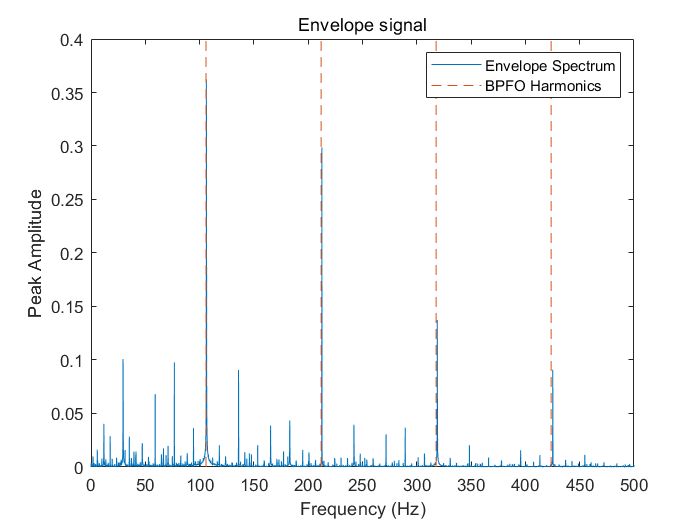

figure
plot(fEnvOuter, pEnvOuter)
xlim([0 500])
ncomb = 10;
helperPlotCombs(ncomb, BPFO)
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: Outer Race Fault')
legend('Envelope Spectrum', 'BPFO Harmonics'),title('Envelope signal')

###      3-10) DE Outer kurtogram

          Frequency, Band Width, and Window size may be obtained through Kourtogram..

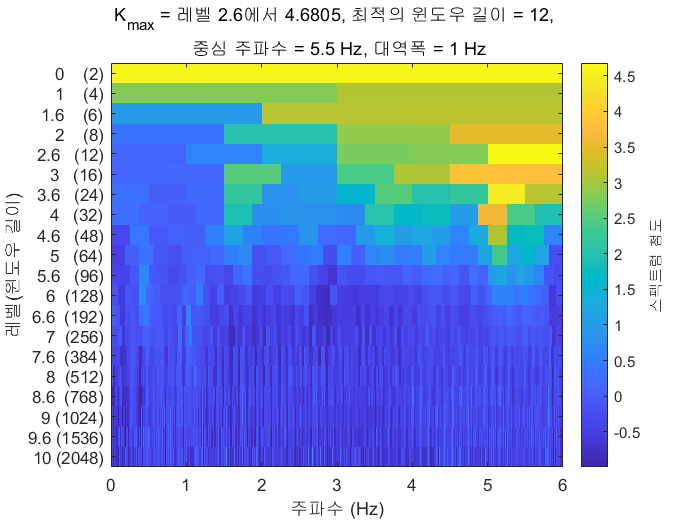

figure
kurtogram(X131_DE_time,12);

[~, ~, ~, fc_outer, wc_outer, BW_outer] =kurtogram(X131_DE_time, fs, 4)

fc_outer = 5500

wc_outer = 12

BW_outer = 1000

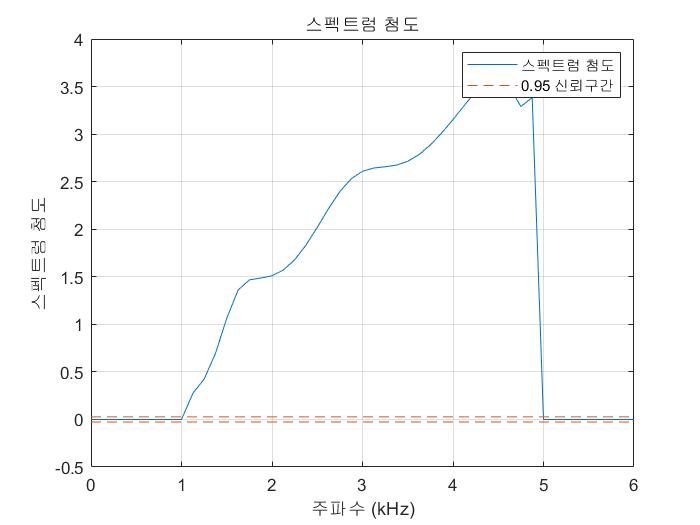

pkurtosis(X131_DE_time,fs,wc_outer)

###       3-11) DE Outer band pass filter

             Design a bandpass filter with the values obtained through Kurtogram.

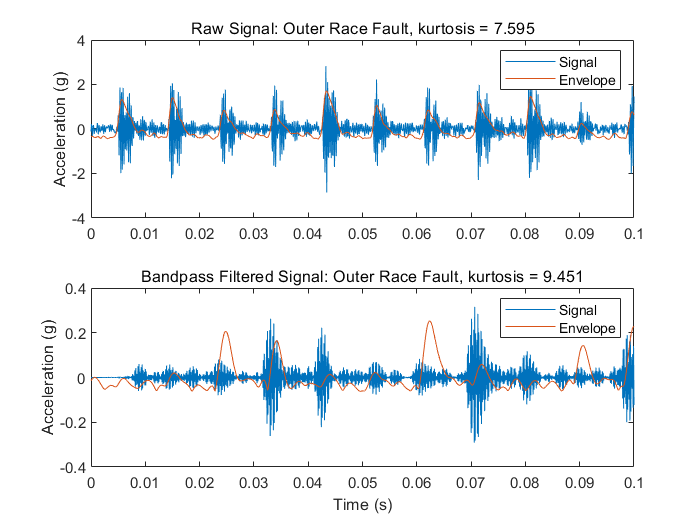

% Design bandpass filter
bpf_outer = designfilt('bandpassfir', 'FilterOrder', 200, 'CutoffFrequency1', 4800, ...
    'CutoffFrequency2', 5500, 'SampleRate', fs);

% Apply bandpass filter
xouterBpf = filter(bpf_outer, X131_DE_time);

% Calculate Kurtosis
kurtouterBpf = kurtosis(xouterBpf);


% Apply bandpass filtered envelope spectrum
[pEnvouterBpf, fEnvouterBpf, xEnvouterBpf, tEnvBpfouter] = envspectrum(X131_DE_time, fs, ...
    'FilterOrder', 200, 'Band', [4800 5500]);

figure
subplot(2, 1, 1)
plot(touter_DE, X131_DE_time,tEnvOuter, xEnvOuter)
ylabel('Acceleration (g)')
title(['Raw Signal: Outer Race Fault, kurtosis = ', num2str(kurtouter)])
xlim([0 0.1])
legend('Signal', 'Envelope')

subplot(2, 1, 2)
plot(touter_DE, xouterBpf, tEnvBpfouter, xEnvouterBpf)
ylabel('Acceleration (g)')
xlim([0 0.1])
xlabel('Time (s)')
title(['Bandpass Filtered Signal: Outer Race Fault, kurtosis = ', num2str(kurtouterBpf)])
legend('Signal', 'Envelope')

###     3-12) DE Outer Bandpass Filter Envelope plot

        Look at the envelope signal to which the band pass filter is applied.

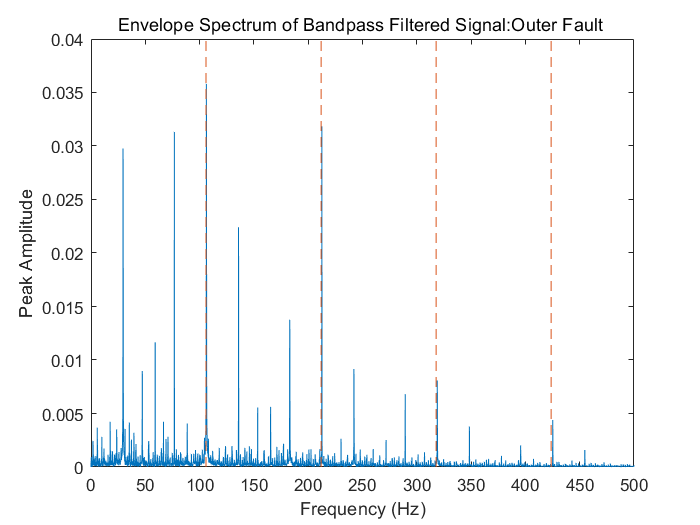

figure
plot(fEnvouterBpf, pEnvouterBpf);
ncomb = 10;
helperPlotCombs(ncomb,BPFO)
xlim([0 500])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum of Bandpass Filtered Signal:Outer Fault ')

## 4. DE Normal

Finally, I will analyze DE normal data.

###     4-1) DE Normal time Features

        It can compare to other fault data in time domain.

normal_time_DE  = timeFeatures(X098_DE_time)

normal_time_DE = 1×14 table
      mean        std         rms         sra         aav       energy     peak       ppv        if        sf        cf       mf         sk         kt  
    ________    ________    ________    ________    ________    ______    _______    ______    ______    ______    ______    _____    ________    ______

    0.012564    0.065152    0.066352    0.045547    0.053471    2130.4    0.34588    0.6634    6.4686    1.2409    5.2129    7.594    -0.17305    2.9306


###     4-2) DE Normal Frequency Features

         It can compare to other fault data in frequency domain.

N_normal = length(X098_DE_time) - 1;

X098_DE_freq = getFFT(X098_DE_time,N_normal);

normal_freq_DE  = freqFeatures(X098_DE_freq)

normal_freq_DE = 1×3 table
        fc           rmsf          rvf    
    __________    __________    __________

    4.1595e-05    0.00019416    0.00018965


###     4-3) DE Normal Time Domain Signal

         It is a graph showing DE normal data in the time domain. 

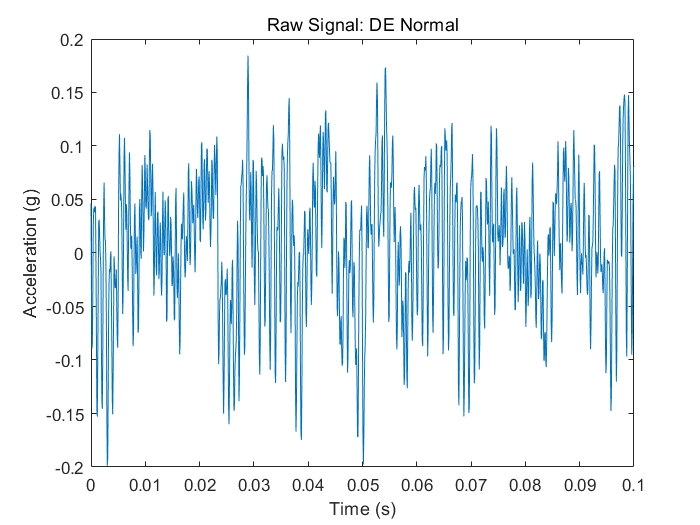

figure
tnormal_DE = (0:length(X098_DE_time)-1)/fs;
plot(tnormal_DE, X098_DE_time)
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Raw Signal: DE Normal')
xlim([0 0.1])

###     4-4) DE Normal **Kurtosis**

         Check kurtosis of DE Normal data in the time domain.

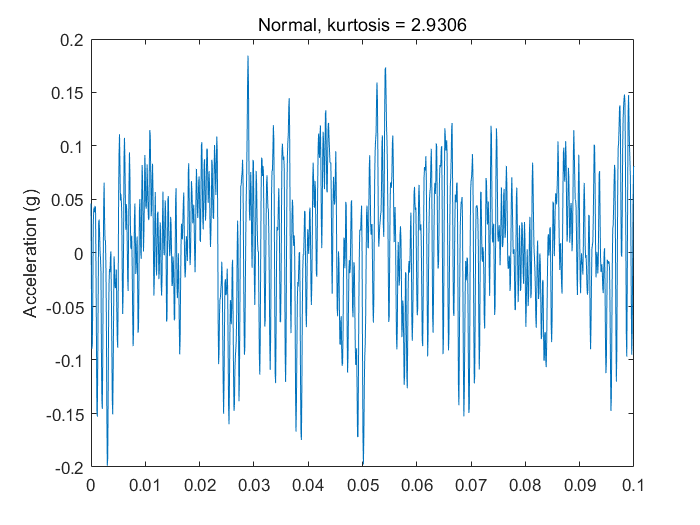

kurtnormal = kurtosis(X098_DE_time);

% Plot
figure
plot(tnormal_DE, X098_DE_time)
ylabel('Acceleration (g)')
title(['Normal, kurtosis = ' num2str(kurtnormal)])
xlim([0 0.1])

###     4-5) DE Normal FFT

         FFT was performed to see the frequency of the DE normal raw data.

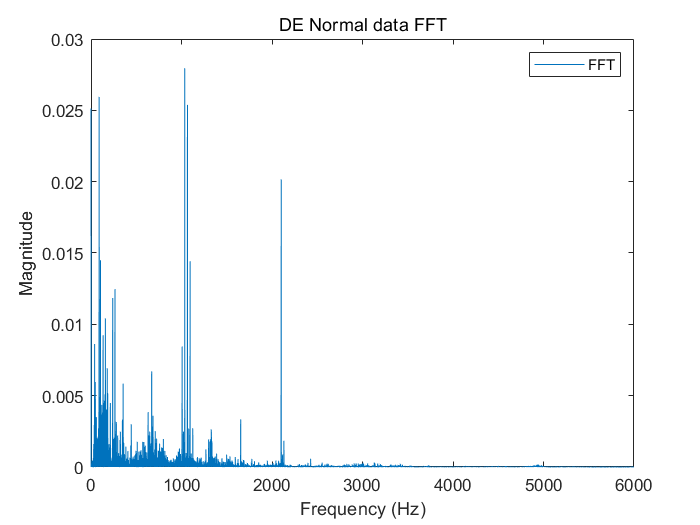

figure
f_normal = 0:fs/N_normal:fs/2;
plot(f_normal, X098_DE_freq)
xlabel('Frequency (Hz)')
ylabel('Magnitude')

title('DE Normal data FFT')
legend('FFT')

###     4-6) DE Normal PSD

        PSD was used to see the square of the DE Normal FFT signal.

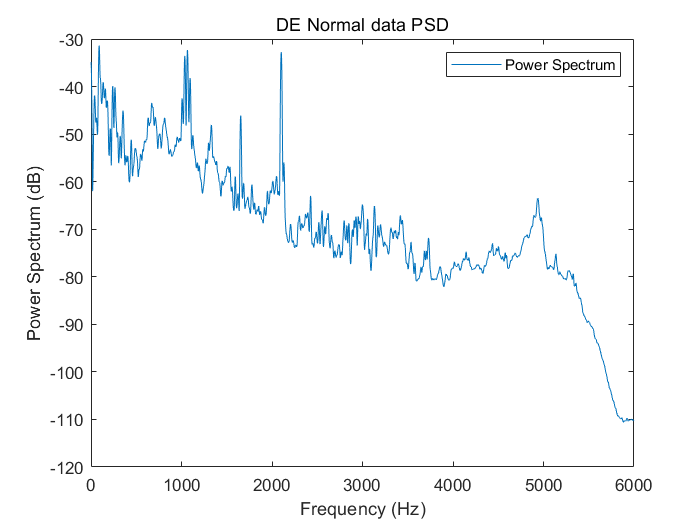

[pnormal, fpnormal] = pspectrum(X098_DE_time,fs);

% Plot
figure
plot(fpnormal, 10*log10(pnormal))
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('DE Normal data PSD')
legend('Power Spectrum')

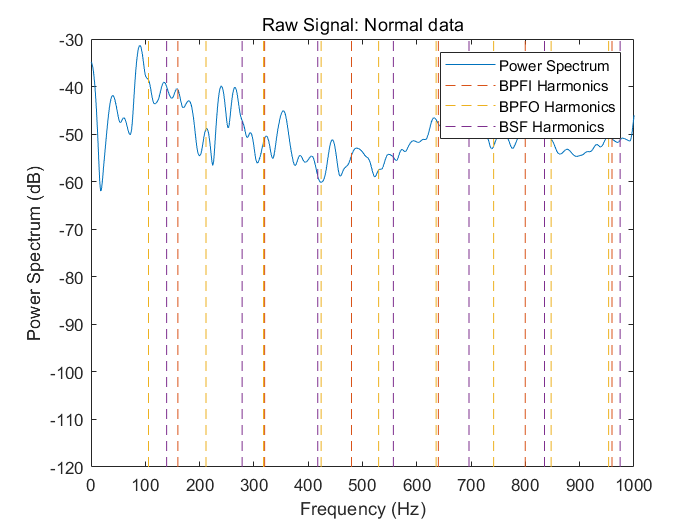

figure
plot(fpnormal, 10*log10(pnormal))
ncomb = 10;
helperPlotCombs(ncomb, [BPFI BPFO BSF])
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('Raw Signal: Normal data')
legend('Power Spectrum','BPFI Harmonics','BPFO Harmonics','BSF Harmonics')

xlim([0 1000])

###      4-7) DE Normal STFT

          STFT is used to see the frequency distribution over time in Normal data.

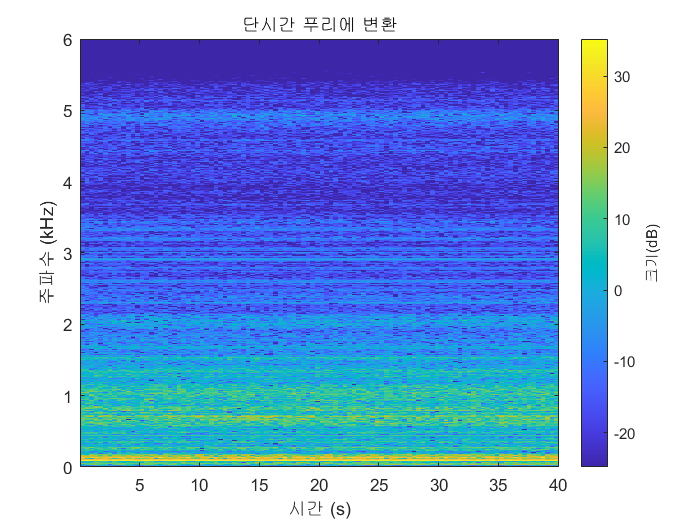

figure
stft(X098_DE_time,fs,'Window',hamming(5120,'periodic'),'OverlapLength',500,'FrequencyRange','onesided');

###      4-8) DE Normal Envelope Extraction

         There is a lot of noise in raw data in front. The envelope method was used to eliminate noise.

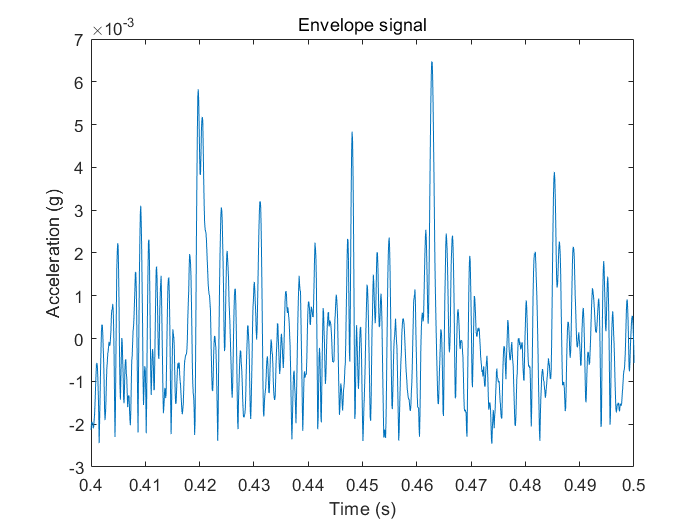

[pEnvnormal, fEnvnormal, xEnvnormal, tEnvnormal] = envspectrum(X098_DE_time,fs);

% Plot
figure
plot(tEnvnormal, xEnvnormal)
xlim([0.4 0.5])
xlabel('Time (s)')
ylabel('Acceleration (g)')
title('Envelope signal')

###    4-9) Normal Envelope FFT

         FFT was used to see the square of the DE normal envelope signal.

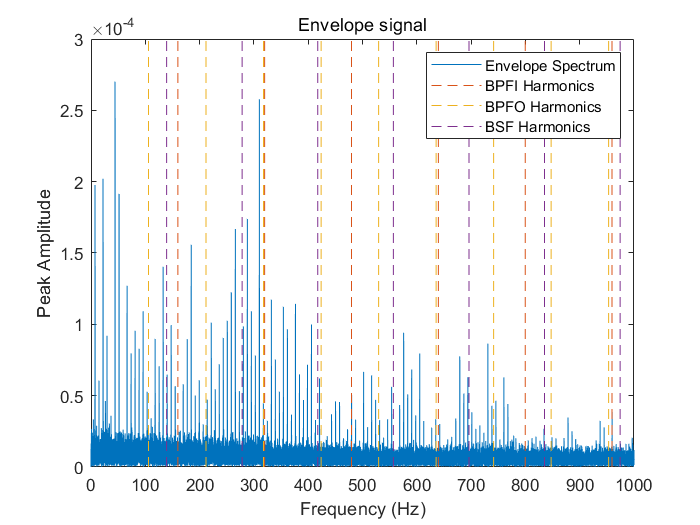

figure
plot(fEnvnormal, pEnvnormal)
xlim([0 1000])
ncomb = 10;
helperPlotCombs(ncomb, [BPFI BPFO BSF])
xlabel('Frequency (Hz)')
ylabel('Peak Amplitude')
title('Envelope Spectrum: Normal data')
legend('Envelope Spectrum', 'BPFI Harmonics','BPFO Harmonics', 'BSF Harmonics'),title('Envelope signal')

         -In the case of normal data, no characteristic frequency appears, so the subsequent analysis process did not proceed.

## **Compare  Features among different classes**

### 1. Time - Feature

Compared with normal DE data, it can be seen that inner data and outer data have increased rapidly in impulse factor and Kurtosis. Through this, it can be determined that the inner and outer sides of the bearing are abnormal. And ball does not show much characteristics in other indicators, but it can be seen that there is an abnormality in the Marginal factor.

And if you look at std, all of them are at least 10 times different from normal DE data. This means that the distribution of signals is far from the average. It can be seen that there is an abnormality in all inner, outer, and ball. There is a difference of at least 10 times in rms, which can be said to be the difference caused by the increase in the maximum peak value due to the influence of noise.

From the energy point of view, the ball is not significant, but it has increased, and the inner and outer have increased by about 10 times. This also shows a different level than normal, so it can be diagnosed as abnormal.

### 2. Frequency - Feature

Looking at fc, ball fc, inner fc, and outer fc are all different from normal. This can be judged to be abnormal. And the rmsf shows the effective value of the frequency, indicating that the frequency is slightly higher in outer and inner, and the ball is not a large dimension, but the frequency is higher. It can be said that it is different from the rmsf of the normal data because all of them have abnormalities. And rvf is an indicator of how much outliers have based on the normal value.

### 3. FFT & PSD

When each raw data is FFT, there is no frequency that appears after about 2000 Hz in normal data. However, there are many frequency signals between 2000 and 4000 Hz in the inner, outer, and ball data. Through this, it can be judged that all three data are failed.

Each fault data has a frequency generated when it fails including BPFO, BPFI and BSF. However, it is not possible to check the frequency when the noise causes the failure. Therefore, we will use the algorithm of the next step.

PSD is the square of the value of FFT, which shows that the value of peak is more prominent. However, even in PSD, the exact fault frequency is not known due to noise.

### 4. STFT

STFT is a technique used to determine at what time zone the frequency is distributed. For all the data, a haning window with a length of 5120 and an STFT with an overlap of 500 were obtained. 

The STFT of the normal data can see values of greater db at 1000 Hz or less at all times. In the fault data of STFT, it can be confirmed that 2000 to 4000 Hz has a large db. The difference between normal data and fault data can be seen through STFT, but the distribution of fault frequency over time is difficult to recognize due to noise.

### 5. Envelop Extraction

The previous FFT, PSD, and STFT could not clearly check the fault frequency due to noise. Therefore, we looked at the data using the envelope technique to remove the carry signal. First, it can be seen that the fault frequency cannot be found even if the normal data is developed and FFT is performed, and there are continuous frequencies that do not have a specific meaning. This is the same as the frequency characteristics when normal.

First, inner has a frequency of BPFI, which is the fault frequency of inner, as a result of FFT after envelope. Through this, it can be diagnosed that the inner is broken. 

Second, as a result of FFT after envelope outer, the outer has a frequency of BPFO, which is the fault frequency of the outer, so it can be diagnosed that the outer has failed. 

Finally, as a result of FFT after envelope ball, it is difficult to check the frequency of BSF because there are still many noises, so it needs to be diagnosed through additional techniques.

### 6. kurtogram & Spectral kurosis

The curtogram represents Spectral kurosis according to the window length in a 2D image. This allows us to obtain a clearer FFT for the fault frequency by applying the band pass filter to the portion with a large frequency kurtosis. It also serves to find the appropriate window size of Spectral kurosisms in the kurtogram.

In the inner kutogram, the section of about 3000 to 4000 Hz shows a large db. Therefore, if the bandpass filter is set to 30004000 and the filtering result is FFT, it is possible to check the harmonics of the BPFI frequency and the RPM frequency of the bare. That is, the inner data can be diagnosed as failing.

The range of about 4800 to 5500 Hz in the outer kutogram shows a large db. Therefore, if the band pass filter is set to [4800 5500] and the filtering result is FFT, it is possible to check the harmonics of the frequency of BPFO and the RPM frequency of the bare. That is, it can be determined that the outer data is also a failure.

The range of about 5375 to 5500 Hz in the kutogram of the ball shows a large db. Therefore, if the band pass filter is set to [5375 5500] and the filtering result is FFT, the frequency of BSF is not confirmed, and the harmonic of the RPM frequency can be confirmed. It can be said that the analysis method of the kurtogram & Spectral kurosis & band pass filter cannot diagnose the failure of the ball. Rather, it is easier to diagnose that FFT, PSD, and STFT are failures compared to normal signals.

### 6. Conclusion

All of them are fault data, but inner and outer were able to diagnose failure in all processes analyzed from all data. Specifically, in the case of ball, the fault frequency could not be confirmed. However, other analyses also showed that the ball was also broken. And it was outer that the most characteristic of the fault was revealed, On the contrary, the ball did not reveal the characteristic of the fault the most.